# BME3053 Final Project

Author: Jeffrey Chen

Group Members: Oriana Molares, Madison Otero

Course: BME 3053C Computer Applications for BME

Term: Spring 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: jeffreychen@ufl.edu

April 7, 2021

% First step is to download WFDB toolbox in order to process
% the .dat files downloaded from the PhyioNet Database

%Sourced from PhysioNet.org
%https://archive.physionet.org/physiotools/matlab/wfdb-swig-matlab/new_version.shtml

[old_path]=which('rdsamp'); if(~isempty(old_path)) rmpath(old_path(1:end-8)); end
wfdb_url='https://physionet.org/physiotools/matlab/wfdb-app-matlab/wfdb-app-toolbox-0-10-0.zip';
[filestr,status] = urlwrite(wfdb_url,'wfdb-app-toolbox-0-10-0.zip');
unzip('wfdb-app-toolbox-0-10-0.zip');
cd mcode
addpath(pwd)
savepath

% This step gives certain functions that help turn the WFDB files into
% readable versions

% Makes an AF folder in the working directory
mkdir AFRAW
addpath('AFRAW');
A = dir('AFRAW\'); 
atrialFolder = string(A(1).folder)+'\files'; % Get's a directory that will contain all AF files

% Makes a NS folder in the working directory
mkdir NSRAW
addpath('NSRAW');
B = dir('NSRAW\'); 
normalFolder = string(B(1).folder)+'\mit-bih-normal-sinus-rhythm-database-1.0.0'; % Get's a directory that will contain all Normal Sinus files

% Downloads the database files for AF and NS and unzips the zip to the
% files made before

% As each zip file is relatively large (~200-300 mb), this may take a while
% to process
ns_url = 'https://physionet.org/static/published-projects/nsrdb/mit-bih-normal-sinus-rhythm-database-1.0.0.zip';
af_url = 'https://physionet.org/static/published-projects/afdb/mit-bih-atrial-fibrillation-database-1.0.0.zip';
urlwrite(af_url, 'AFRAW.zip')
unzip('AFRAW.zip', 'AFRAW')
urlwrite(ns_url, 'NSRAW.zip')
unzip('NSRAW.zip', 'NSRAW')

% Makes a folder in the working directory to place the exported files
mkdir readfiles
addpath('readfiles');
A = dir('readfiles\'); 
folder_dir = A(1).folder; % Get's a directory that will contain all read files

% Given that the two databases are downloaded already (MIT-BIH Normal Sinus
% Rhythm) and (MIT-BIH Atrial Fibrillation), we will iterate through the
% files and convert 3 records into .mat and then subsequently break the
% file down into readable information using WFDB functions. 

% Folder search sourced and modified from MatLab Wiki
% (https://matlab.fandom.com/wiki/FAQ)

% Checks to see if the folder is proper
if ~isfolder(atrialFolder)
    error = fprintf('Error: The following folder does not exist:\n%s\nPlease specify a new folder.', atrialFolder);
else
    % Parses through folder for .dat files. Obtains the first 3 viable records
    % to be converted into an MAT file using wfdb2mat, extracts the relevant
    % information using rdmat, then saves the workspace data
    cd(atrialFolder);
    filePattern = fullfile(atrialFolder, '*.dat');
    files = dir(filePattern); % Obtains directory of all .dat files
    for i = 1 : 3
        baseFile = files(i).name;
        fullFile = fullfile(files(i).folder, baseFile);
        [~,name,~] = fileparts(fullFile); % isolates the name of the file
        wfdb2mat(name) % converts to .mat file
        matname = string(name) + 'm'
        [tm,signal,Fs,labels]=rdmat(char(matname)); % reads certain values of the signal mat file
        cd(folder_dir) % Save to new directory
        save(matname+'_read', 'Fs', 'labels', 'signal', 'tm')
        cd(atrialFolder) % Return to old directory with all relevant files
    end
end

matname = "04015m"

matname = "04043m"

matname = "04048m"

% Repeat the same steps above with the Normal Database

% Checks to see if the folder is proper
if ~isfolder(normalFolder)
    error = fprintf('Error: The following folder does not exist:\n%s\nPlease specify a new folder.', normalFolder);
else
    % Parses through folder for .dat files. Obtains the first 3 viable records
    % to be converted into an MAT file using wfdb2mat, extracts the relevant
    % information using rdmat, then saves the workspace data
    cd(normalFolder);
    filePattern = fullfile(normalFolder, '*.dat');
    files = dir(filePattern); % Obtains directory of all .dat files
    for i = 1 : 3
        baseFile = files(i).name;
        fullFile = fullfile(files(i).folder, baseFile);
        [~,name,~] = fileparts(fullFile); % isolates the name of the file
        wfdb2mat(name) % converts to .mat file
        matname = string(name) + 'm'
        [tm,signal,Fs,labels]=rdmat(char(matname)); % reads certain values of the signal mat file
        cd(folder_dir) % Save to new directory
        save(matname+'_read', 'Fs', 'labels', 'signal', 'tm')
        cd(normalFolder) % Return to old directory with all relevant files
    end
end

matname = "16265m"

matname = "16272m"

matname = "16273m"

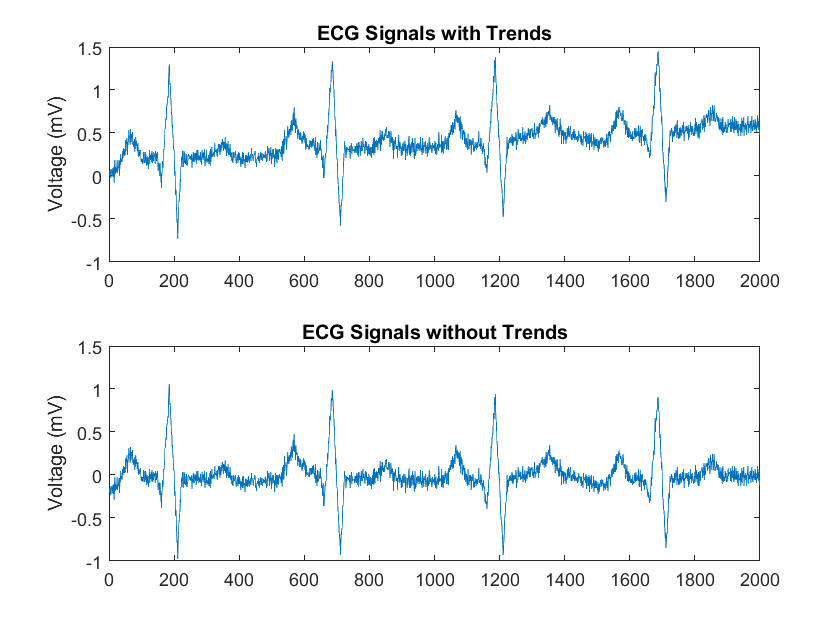

% First we will detrend the ECG signal data in order to remove patterns
% that might not be from the ECG data (i.e. sensor drift)

% Here is an example of a detrended signal modified from MathWorks
% documentation
load('ecgSignals.mat')
t = (1:length(ecgl))';

subplot(211)
plot(t, ecgl)
title('ECG Signals with Trends')
ylabel('Voltage (mV)')

subplot(212)
plot(t, detrend(ecgl))
title('ECG Signals without Trends')
ylabel('Voltage (mV)')

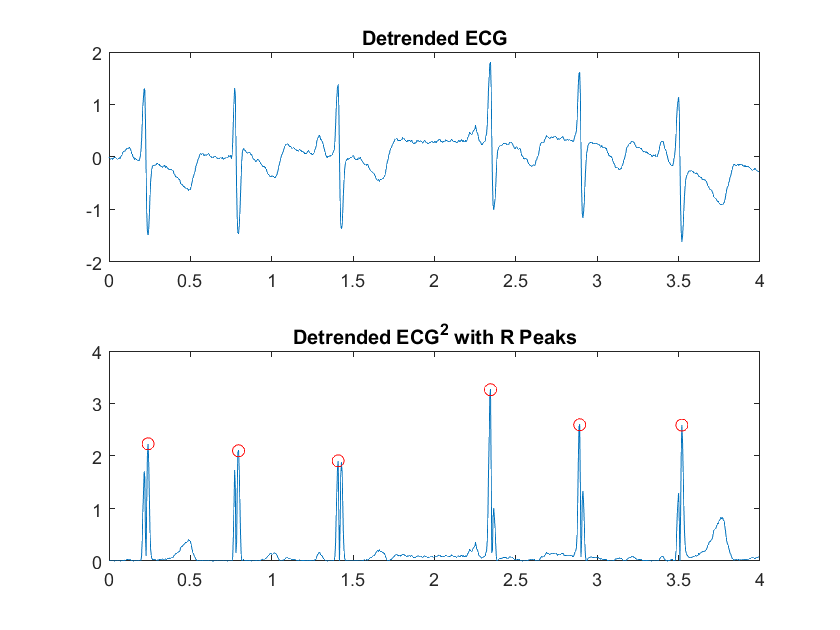

% As we are going to take data points at 1000 points of time (~ 4 QRS
% complexes), it is unlikely that we will encounter complicated polynommial
% trends, so the use of a linear detrend should be adequate. 

% Here is an example using a predetermined ECG.mat file

cd(folder_dir)
load 04015m_read.mat % example read file generated, should be the first one in the code if followed correctly
dt_signal = detrend(signal);

% Our plan is to use Linear Discriminant Analysis with 2 classes to
% generate a classification between Atrial Fibrillation and Normal ECGs

% The first variable we will look at is in the variance in period between
% QRS complexes. To accomplish this, we will find the peak (R) of the first
% encountered QRS complex of each 1000 point set, and compare the distance
% for each subsequent peak in the set. Then we will find the variance using
% the var function in MATLAB

subplot(211)
plot(tm(1:1000), dt_signal(1:1000,1))
title('Detrended ECG')
subplot(212)
dt_signal_peak = abs(dt_signal).^2; % square signals to emphasize peaks
plot(tm(1:1000), dt_signal_peak(1:1000, 1))
title('Detrended ECG^2 with R Peaks')
hold on
% Now we find the peaks
[qrspeaks,locs] = findpeaks(dt_signal_peak(1:1000),tm(1:1000),'MinPeakHeight',(max(dt_signal_peak(1:1000, 1)))/2,...
    'MinPeakDistance',0.150); 
plot(locs,qrspeaks,'ro')
hold off


% Now we take the variance in R peak distances, but we first need to
% evaluate the distance between each subsequent peak

locs_diff = [];
for i = 1:1:length(locs)-1
    diff = locs(i+1) - locs(i);
    locs_diff = [locs_diff diff]; 
end
r_var = var(locs_diff) % Find the variance in the distance between each peak (R-R interval)

r_var = 0.0257


% The second class that we are going to observe is the mean squared error
% of the values from the baseline of zero @ the isoelectric point. As
% atrial fibrillation ECGs appear to lack a p-wave, the mean squared error
% should be lower than that of normal sinus rhythm

mse = mean(dt_signal(1:1000,1)).^2

mse = 5.1009e-05

% Now we will go through the dataset of ECG data in only the first
% electrode (i.e. the signal data has 2 columns of data for two different
% electrodes, but we will iterate only through the first column). For every
% 1000 signals, we will take the r_var and mse and save it to dat files

% Vector to store MAT file names
matFiles = [];

% Checks to see if the folder is proper
if ~isfolder(folder_dir)
    error = fprintf('Error: The following folder does not exist:\n%s\nPlease specify a new folder.', folder_dir);
else
    % Obtains all the names of the .mat files and places them in one vector
    cd(folder_dir);
    filePattern = fullfile(folder_dir, '*.mat');
    files = dir(filePattern);
    for i = 1 : 6
        baseFile = files(i).name;
        fullFile = fullfile(files(i).folder, baseFile);
        [~,name,ext] = fileparts(fullFile);
        mat_name = strcat(name, ext)
        matFiles = [matFiles string(mat_name)];
    end
end

mat_name = '04015m_read.mat'

mat_name = '04043m_read.mat'

mat_name = '04048m_read.mat'

mat_name = '16265m_read.mat'

mat_name = '16272m_read.mat'

mat_name = '16273m_read.mat'


% Now we will iterate through the signals and take 400 sets of each
% thousand signal values, generating a r_var and mse for every set,
% resulting in 1200 r_var and mse values for both the atrial fibrillation
% and normal ECGs

r_vars = []; % Track the r_var
mse_vals = []; % Track mean square errors
type = []; % Track which type of ECG.
count = 1; % Since first three ECG .mat files are AF, this helps keep track

for i = 1:length(matFiles) % Iterates through all the mat files
    load(matFiles(i));
    signal(:,2) = []; % Deletes second ECG signal as not used
    dt_signal = detrend(signal); % Detrend signals
    dt_signal_peak = abs(dt_signal).^2; % Emphasize peaks
    for j = 1:400 % Iterate 400 times through signals to get 400 data sets
        [qrspeaks,locs] = findpeaks(dt_signal_peak(1:1000),tm(1:1000),'MinPeakHeight',(max(dt_signal_peak(1:1000, 1)))/2,...
        'MinPeakDistance',0.150); % Finds the peak signals and the locations
        locs_diff = []; % Stores the difference in locations
        for k = 1:1:length(locs)-1 % Finds the difference in R-R peaks
            diff = locs(k+1) - locs(k);
            locs_diff = [locs_diff diff]; 
        end
        r_var = var(locs_diff); % Calculates variance in R-R peaks
        r_vars = [r_vars r_var]; % Adds an r_var to the list
        mse = mean(dt_signal(1:1000,1)).^2; % Calculates mean squared error of detrended signal
        mse_vals = [mse_vals mse]; % Adds an MSE to the list
        dt_signal_peak(1:1000) = []; % Removes first 1000 peak signals so loop can repeat
        tm(1:1000) = []; % Removes first 1000 time signals so loop can repeat
        
        % Keeps track of which type of ECG, since the first 3 are AF
        if count <4
            type = [type 1]; % 1 represents atrial fibrillation
        else
            type = [type 2]; % 2 represents normal sinus 
        end
        
    end
    % Increases the count to specify which .mat file we are at
    count = count + 1;
end

Unrecognized function or variable 'matFiles'.

% Turn horizontal vectors into vertical vectors, then horizontally
% concatenate variables.
signal_data = horzcat(r_vars', mse_vals', type'); 
% Data in table form for easy viewing
signal_data_T = array2table(signal_data, 'VariableNames', {'R-R Interval', 'Mean Squared Error of Signals', 'Type (1=AF, 2=NS)'}); 
% Save data as a .dat file for easy use of LDA
writetable(signal_data_T, 'signal.dat')
disp(signal_data_T)

    R-R Interval    Mean Squared Error of Signals    Type (1=AF, 2=NS)
    ____________    _____________________________    _________________

       0.025696              5.1009e-05                      1        
       0.029092              5.1009e-05                      1        
       0.024939              5.1009e-05                      1        
       0.049054              5.1009e-05                      1        
       0.037275              5.1009e-05                      1        
     0.00021867              5.1009e-05                      1        
      0.0031436              5.1009e-05                      1        
       0.013467              5.1009e-05                      1        
       0.056483              5.1009e-05                      1        
        0.12067              5.1009e-05                      1        
       0.037088              5.1009e-05      

% Now we can observe the data in a scatter plot
warning off;
signal = readmatrix('signal.dat'); % Allows for the importing of data with NaN values

% Assigns new variables based on signal.dat file
R_R = signal(:,1);
MSE = signal(:,2);
Type = signal(:,3);

% Remove NaN values in R_R and its associated variables in MSE and Type for
% consistency

 nan_loc = find(isnan(R_R));
 for i=length(nan_loc):-1:1
     R_R(nan_loc(i),:) = [];
     MSE(nan_loc(i),:) = [];
     Type(nan_loc(i),:) = [];
 end



% Application of LDA
lda = fitcdiscr([R_R, MSE], Type);
ldaClass = resubPredict(lda);

% Calculate Resub Error
ldaResubErr = resubLoss(lda);
fprintf('LDA error is %.3f', ldaResubErr)

LDA error is 0.163

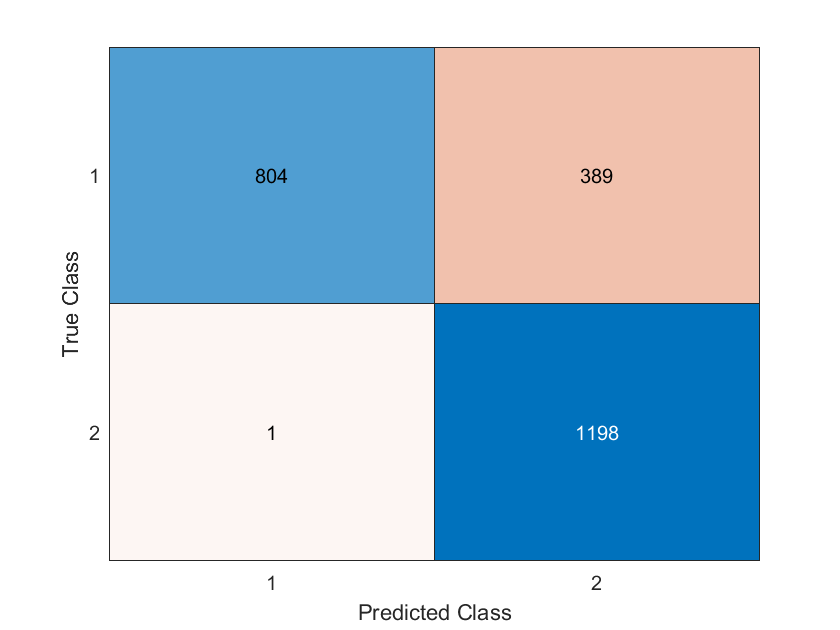


% Confusion Chart
ldaResubCM = confusionchart(Type, ldaClass);

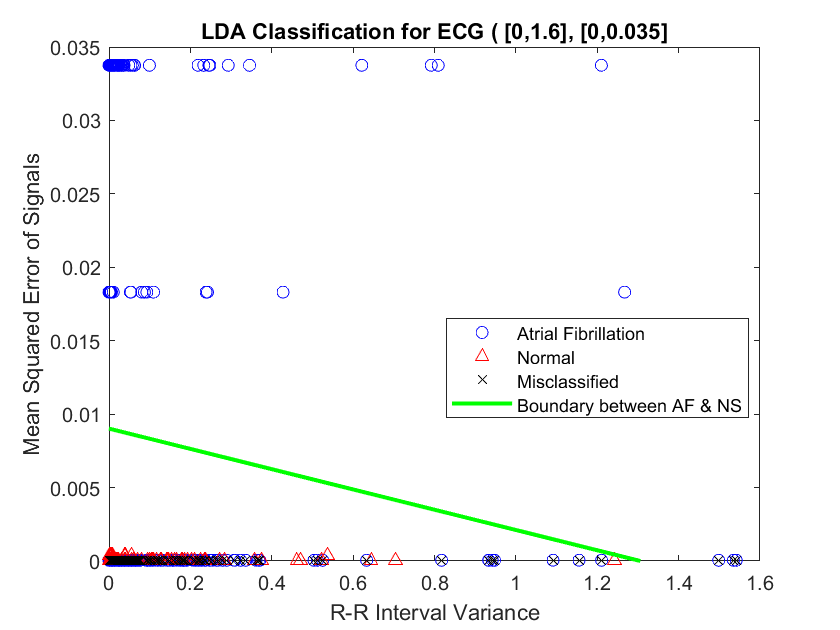


% Using a gscatter to visualize misclassified points
figure(1)
gscatter(R_R, MSE, Type, 'br','o^')
xlabel('R-R Interval Variance')
ylabel('Mean Squared Error of Signals')
bad = ldaClass ~= Type; % Identified misclassified points
hold on
plot(signal(bad,1), signal(bad,2), 'kx'); % Plots misclassified points
title('LDA Classification for ECG ( [0,1.6], [0,0.035]')
legend('Atrial Fibrillation', 'Normal', 'Misclassified')
xlim([0 1.6])
ylim([0 0.035])

% Generate line marking boundary genereated by LDA
K = lda.Coeffs(1,2).Const; 
L = lda.Coeffs(1,2).Linear;
f = @(x1,x2) K + L(1)*x1 + L(2)*x2;
h2 = fimplicit(f,[0 8 0 0.1]);
h2.Color = 'g';
h2.LineWidth = 2;
h2.DisplayName = 'Boundary between AF & NS';
hold off

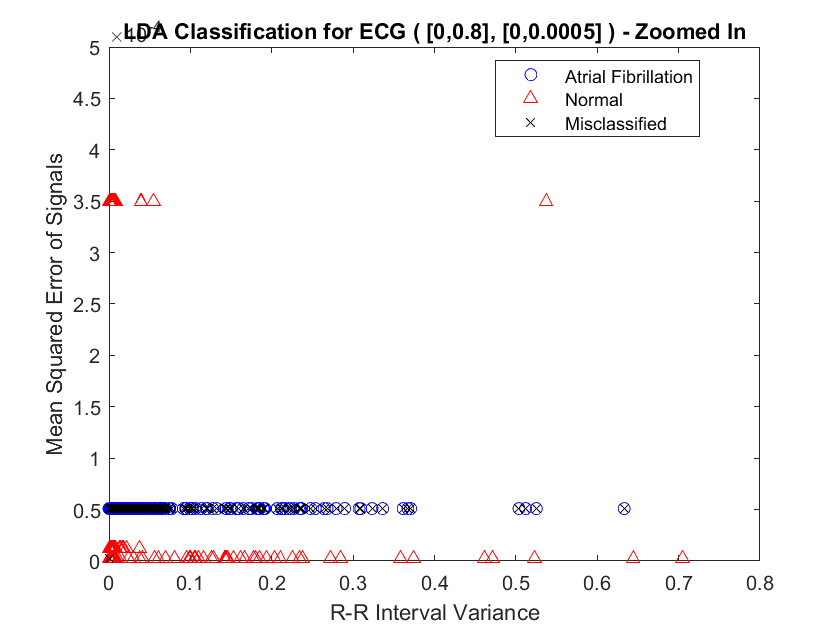


% Zoomed in picture of bottom left quadrant
figure(2)
gscatter(R_R, MSE, Type, 'br','o^')
xlabel('R-R Interval Variance')
ylabel('Mean Squared Error of Signals')
bad = ldaClass ~= Type; % Identified misclassified points
hold on
plot(signal(bad,1), signal(bad,2), 'kx'); % Plots misclassified points
title('LDA Classification for ECG ( [0,0.8], [0,0.0005] ) - Zoomed In')
legend('Atrial Fibrillation', 'Normal', 'Misclassified')
xlim([0 0.8])
ylim([0 0.0005])
hold off

% Now we can use the lda class generated to predict AF vs NS given values
% of R-R Interval Variance and Mean Squared Error of Signals

% Here is an example using the mean of both values
mean_R = mean(R_R);
mean_MSE = mean(MSE);
z = predict(lda, [mean(R_R), mean_MSE]);
if z == 1
    fprintf('Atrial Fibrillation')
else
    fprintf('Normal Sinus')
end

Normal Sinus

**Model Performance Metrics:**

Accuracy = 83.70%

Precision = 75.49%

Sensitivty = 99.92%

Specificity = 67.39% 